# Figure S5G

### Load data

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files\A080_dataIF\';

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
       
     

        
     '500nM TAK',2:7,2,1,0; %1
   '250nM TAK',2:7,3,1,0; %1
      '125nM TAK',2:7,4,1,0; %1
         '62.5nM TAK',2:7,5,1,0; %1
            '31.25nM TAK',2:7,6,1,0; %1
               '15.6nM TAK',2:7,7,1,0; %1
                  '6nM TAK',2:7,8,1,0; %1
                     '3nM TAK',2:7,9,1,0; %1
                        '1nM TAK',2:7,10,1,0; %1
                           'DMSO',2:7,11,1,0; %1
    
    
      
       % 
       };



S = loadData_IF(conditions, dataDir);

all_row = [2:7];
CDC7_row = [2:4];
CDK_row = [5:7];
all_col = [2:11];

**Gate cells**

xthresh = 0.63e6;
xrange = linspace(0,1.1e6,1000);

for i = 1:length(S)
    S(i).dnaN = NaN*ones(size(S(i).DNA));
    for r = 1:8
        for c = 1:12
            inds = S(i).wellindex(:,1) == r & S(i).wellindex(:,2) == c;
            if sum(inds) > 0
                xdata = S(i).DNA(inds);
                [f, xi] = ksdensity(xdata,xrange);
                xi_trunc = xi(xi<xthresh);
                f_trunc = f(xi<xthresh);
                [~, maxi] = max(f_trunc);
                N_peak = xi_trunc(maxi);
                S(i).dnaN(inds) = 2*S(i).DNA(inds)/N_peak;
            end
        end
    end
end


S5G

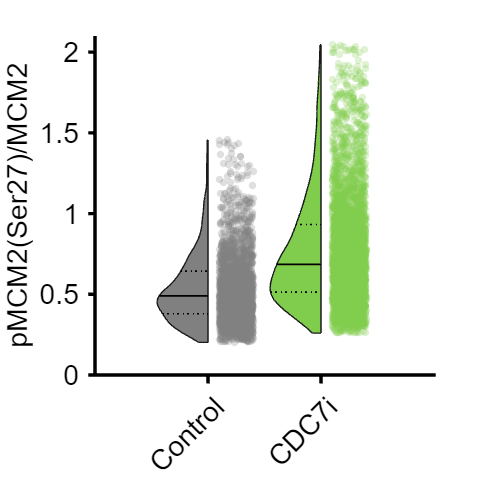

ans = 2363

ans = 3777

p = 1.2258e-125

conds=[10 1] ;

offset=0;
ally = [];
groups = [];

yval = 'YFP1';
poi_list=[1];
gateVals = {'dnaN','iRFP1'};
rangeVals = {[2.5 3.5],[2^9 2^13 ]}; 
edges = linspace(12,14,30);
row_gate = [5:7];
col_gate = [2:11];

colors = [.5 .5 .5; .5 .8 .3];
  f1= figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
   hold on

name = {'mitosis'};
lims = {[0 6],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
     
        ydata = [];
        plot_ydata=[];

       ydata(:, 1) = (((S(conds(i)).iRFP1)));
        ydata(:, 2) = 2*(S(conds(i)).DNA);
        ydata(:, 3) = ((S(conds(i)).YFP1));
        ydata(:,4) = ydata(:,3)./ydata(:,1);
    

           yvals = ydata(:,4);

     
  rows = S(conds(i)).wellindex(:,1);
     cols = S(conds(i)).wellindex(:,2);
        
    totalGate = true(size(yvals,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(conds(i)).(gateVals{gate})<rangeVals{gate}(2) & S(conds(i)).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
     
    end
    

    yvals = yvals(totalGate & any(rows == row_gate,2)  & any(cols == col_gate,2));

  
perc99(i)=prctile(yvals,99);  
perc1(i)=prctile(yvals,1); 

 ind = yvals > perc1(i) & yvals <perc99(i);
 sum(ind)



   plot_ydata = yvals(ind);

    ally = [ally;  plot_ydata];
    groups = [groups; repmat(i,size( plot_ydata))];





    end




       cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);

        set(gca,'linewidth',2,'fontsize',17)
      xticklabels({'Control','CDC7i'})

  ylim([0 2.1])
 xtickangle(45)
set(gca,'fontsize',17)
 p=mediantest(ally(groups==1),ally(groups==2))



ylabel('pMCM2(Ser27)/MCM2')

   % print_pdf(['fig_S5G.pdf'])
end